g=@(x,a) a.*x.*(1-x);
f=@(x,a) a.*x^2+(1-a).*x;
syms a x;
expand(x-g(x,a))

$$ans = x-a\,x+a\,x^{2}$$

expand(f(x,a))

$$ans = x-a\,x+a\,x^{2}$$


equation= x == g(x,a)

$$equation = x=-a\,x\,\left(x-1\right)$$

S= solve(equation)

$$S = \left(\begin{array}{c} 0\\ \frac{a-1}{a} \end{array}\right)$$


syms derivative(x,a)
derivative(x,a) = diff(g(x,a),x)

$$derivative(x, a) = -a\,x-a\,\left(x-1\right)$$

d(1)=derivative(S(1),a)

$$d = \left(\begin{array}{cc} a & 2-a \end{array}\right)$$

d(2)=simplify(derivative(S(2),a))

$$d = \left(\begin{array}{cc} a & 2-a \end{array}\right)$$

d

$$d = \left(\begin{array}{cc} a & 2-a \end{array}\right)$$


%podmínky konvergence
abs(d(1))<1

$$ans = \left|a\right|<1$$

abs(d(2))<1

$$ans = \left|a-2\right|<1$$

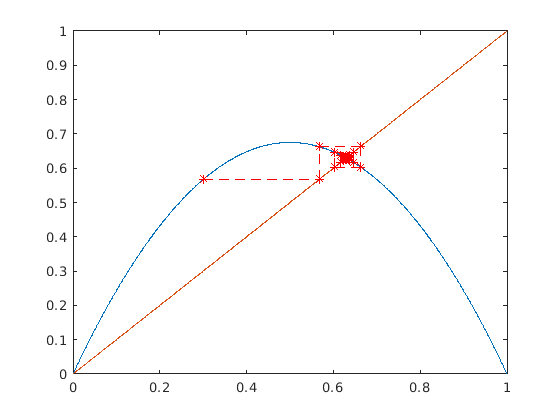


%plot cobweb
a=2.7;
x=0.3;
xx=linspace(0,1,1000);
plot(xx,g(xx,a),xx,xx)
hold on
gx=g(x,a);
plot(x,gx,"r*")
plot(gx,gx,"r*")
for k=1:20
    pause(0.5)
    plot([x,gx],[gx,gx],"r--*")
    x=gx;gx=g(x,a);
    plot([x,x],[x,gx],"r--*")
end
hold off